% define variables


t = c001_Time*1000;
in = [c002_Membrane_Voltage_1; c003_Membrane_Voltage_1; c004_Membrane_Voltage_1; c005_Membrane_Voltage_1; c006_Membrane_Voltage_1; c007_Membrane_Voltage_1; c008_Membrane_Voltage_1; c009_Membrane_Voltage_1; c010_Membrane_Voltage_1; c011_Membrane_Voltage_1; c012_Membrane_Voltage_1]*1000;
%in = [c002_Membrane_Voltage_2; c003_Membrane_Voltage_2; c004_Membrane_Voltage_2; c005_Membrane_Voltage_2; c006_Membrane_Voltage_2; c007_Membrane_Voltage_2; c008_Membrane_Voltage_2; c009_Membrane_Voltage_2; c010_Membrane_Voltage_2; c011_Membrane_Voltage_2; c012_Membrane_Voltage_2]*1000;
cmd = [-0.1; -0.08; -0.06; -0.04; -0.02; 0; 0.02; 0.04; 0.06; 0.08; 0.1];



% baseline sweeps 

for k = 1:11
    baseline(k) = mean(in(k,3400:4000));
end



a = baseline';

in = in - a;



% measure the stable state membrane voltage at the end of each step 
% measure final 30 ms in each step, data points 23400:24000



for k = 1:11
    step(k) = mean(in(k,23400:24000));
end

step = step'

step =    -5.8016
   -4.8667
   -3.5977
   -2.4209
   -1.1390
   -0.1560
    1.6546
    2.4170
    4.0081
    5.1225





% create a linear fit of the data to determine the input resistance

Rin_fit = fitlm(cmd, step)

Rin_fit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.15007     0.056049    2.6775      0.025309
    x1              62.001      0.88622    69.962    1.2585e-13


Number of observations: 11, Error degrees of freedom: 9
Root Mean Squared Error: 0.186
R-squared: 0.998,  Adjusted R-Squared: 0.998
F-statistic vs. constant model: 4.89e+03, p-value = 1.26e-13

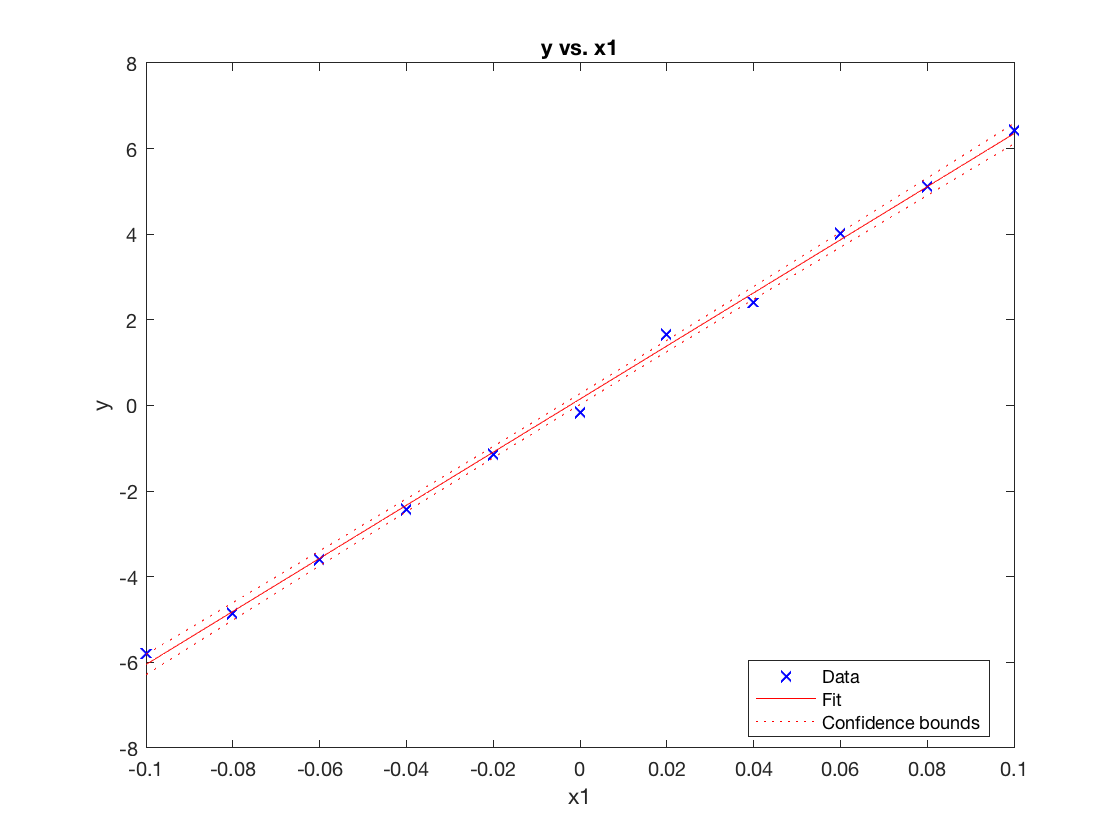

figure
plot(Rin_fit)

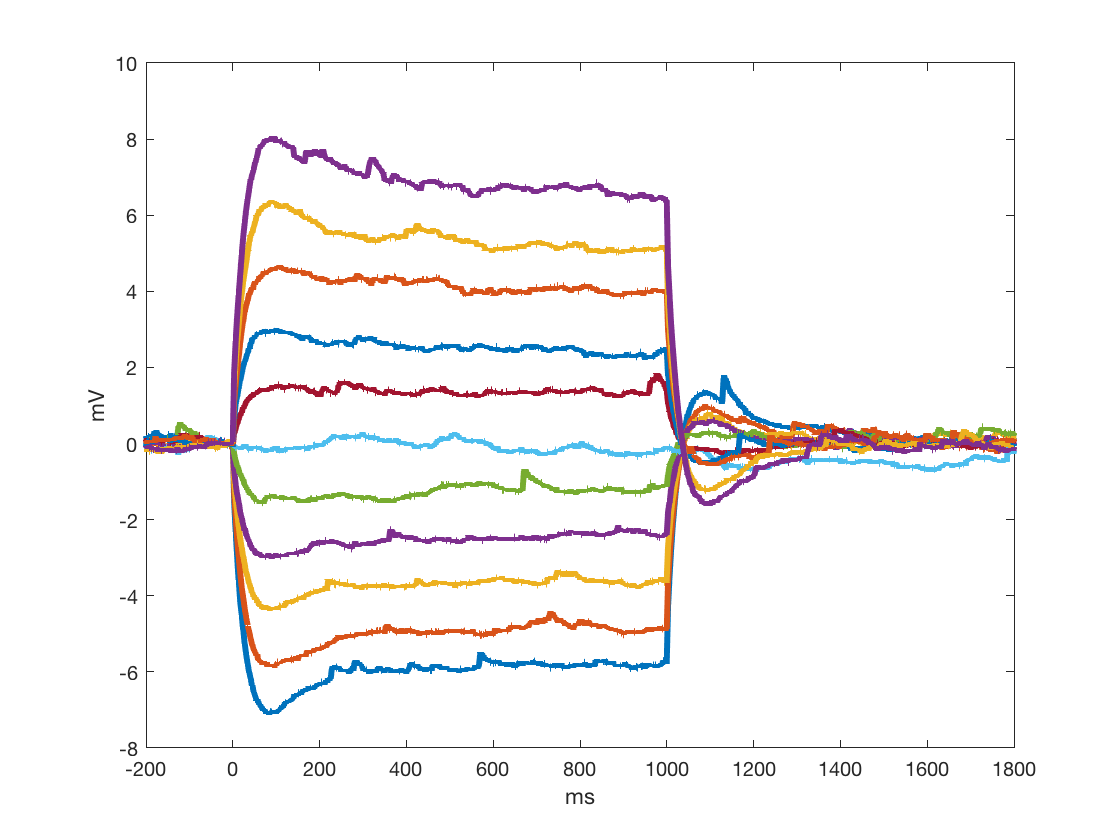

Rin_fit = Rin_fit.Coefficients{end,1};




% measure the time constant tau and derive the membrane capacitance (Cm)

% start by setting the time to 0 at the beginning of the current steps

t_zero = t - 200;
figure;
plot(t_zero,in,'LineWidth',3);
ylabel('mV');
xlabel('ms');


% tau is the time is takes for an exponential curve to reach 63.2% of its
% maximum value, so multiply each element of step by 0.632 and then find
% the time point (in ms) at which that value is reached in each step


for k = 1:5
    tau_Vm(k) = -step(k)*0.632;
    Tau = find(-in(k,:)>tau_Vm(k));
    Tau = min(Tau);
    Tau_t(k) = t_zero(Tau);
    Cm(k) = (Tau_t(k)/1000)/(Rin_fit/1000000);
end



for k = 7:11
    tau_Vm(k-1) = step(k)*0.632;
    Tau = find(in(k,:)>tau_Vm(k-1));
    Tau = min(Tau);
    Tau_t(k-1) = t_zero(Tau);
    Cm(k-1) = (Tau_t(k-1)/1000)/(Rin_fit/1000000);
end


Tau_t_mean = mean(Tau_t)

Tau_t_mean = 15.8300

Cm_mean = mean(Cm(:))

Cm_mean = 255.3165

Rin_fit

Rin_fit = 62.0015


a = [Rin_fit; Tau_t_mean; Cm_mean];

